clear all;


%---------------------------------
% Reads Recored IMU Data
% Plots Time Series Graphs
% Computes Error Metrics

filePath = "DataSets/RawIMU.csv";

% Read the CSV file into a table
dataTable = readtable(filePath);

AX = dataTable.AX;
AY = dataTable.AY;
AZ = dataTable.AZ;
GX = dataTable.GX;
GY = dataTable.GY;
GZ = dataTable.GZ;
PITCH = dataTable.PITCH; % MCU Kalman Filter Output
ROLL = dataTable.ROLL; % MCU Kalman Filter Output




% Compute Raw Angle Estimate From Accelerometer

pitch_raw = zeros(size(PITCH));

for i = 1:1:length(pitch_raw)
    pitch_raw(i) = rad2deg(atan2(-AX(i),AZ(i)));
end

% Compute PSD 


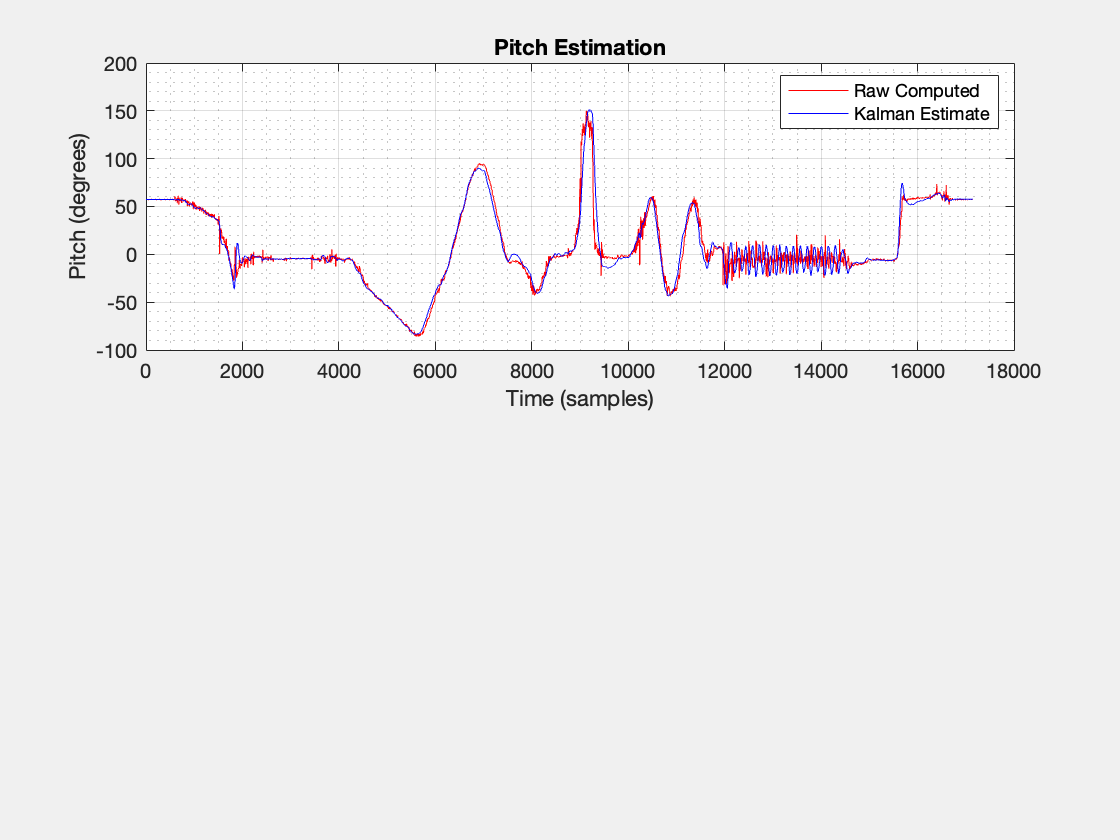

% Plot the results
fig = figure;

% Plot for Pitch
subplot(2,1,1); 
plot(pitch_raw, 'r'); hold on;  % Raw computed pitch (from accelerometer)
plot(PITCH, 'b'); hold off;
hold off; grid on;
grid minor;
title('Pitch Estimation');
xlabel('Time (samples)');
ylabel('Pitch (degrees)');
legend('Raw Computed', 'Kalman Estimate');

set(fig, "Visible", "on")